A = 1

A = 1

T_chair = 10

T_chair = 10

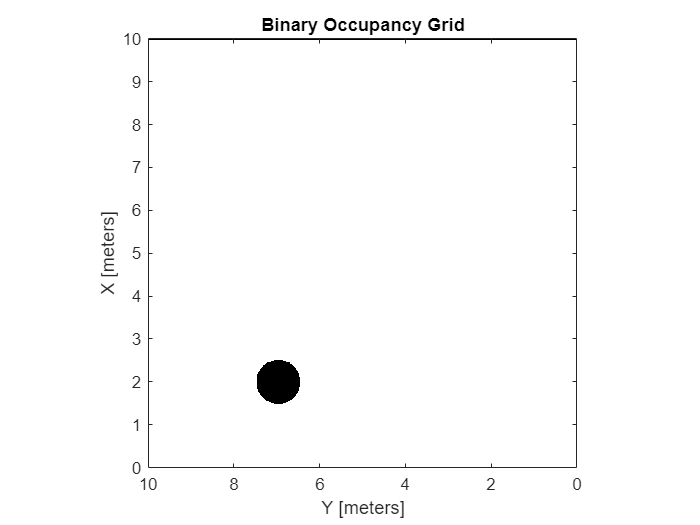


lidar = rangeSensor("Range",[0 1], "HorizontalAngleResolution", 2*pi/90);

show(chair_map(chair_center(0.05, A, T_chair)))
view(-90,90)


% p_start = [1 7];
% p_end = [7 7];
p_start = [2 9];
p_end = [2.1 2];
pts = [p_start; p_end];

T = 0.05; % Sampling period


poten = ctrl_potential();
poten.v_max = 1;
poten.k_goal = 10;
poten.avoidance_strength = 0.1;

poten.avoidance_distance = 0.1;
%poten.avoidance_distance = 1;

poten.robot_radius = 0.2;

N = 1e3

N = 1000

state_hist = {}


state_hist =

  0×0 empty cell array



legend_str = []


legend_str =

     []



for trial = 1:4
    robot_state = p_start;
    state_hist{trial} = NaN(N, 2);
    if trial == 1
        A = 2; T_chair = 1;
    elseif trial == 2
        A = 2; T_chair = 10;
    elseif trial == 3
        A = 5; T_chair = 1;
    elseif trial == 4
        A = 5; T_chair = 10 ;
    end
    
    
    for i = 1:N
        state_hist{trial}(i,:) = robot_state;
    
        [ranges,angles] = lidar([robot_state 0],chair_map(chair_center(i*T, A, T_chair)));
        v_xy = poten.step(robot_state, p_end, ranges, angles);
    
        robot_state = robot_state + v_xy * T;
    
        if norm(robot_state - p_end) < 1e-2
            break
        end
    end
    disp("Time:" + i * T + " sec")
    legend_str = [legend_str "A = " + A + ", T = " + T_chair + " | t_{goal} = " + i*T]
end

Time:8.45 sec


legend_str = "A = 2, T = 1 | t_{goal} = 8.45"

Time:10.95 sec


legend_str = 1×2 string array
    "A = 2, T = 1 | t_{goal} = 8.45"    "A = 2, T = 10 | t_{goal} = 10.95"


Time:8.55 sec


legend_str = 1×3 string array
    "A = 2, T = 1 | t_{goal} = 8.45"    "A = 2, T = 10 | t_{goal} = 10.95"    "A = 5, T = 1 | t_{goal} = 8.55"


Time:7.65 sec


legend_str = 1×4 string array
    "A = 2, T = 1 | t_{goal} = 8.45"    "A = 2, T = 10 | t_{goal} = 10.95"    "A = 5, T = 1 | t_{goal} = 8.55"    "A = 5, T = 10 | t_{goal} = 7.65"


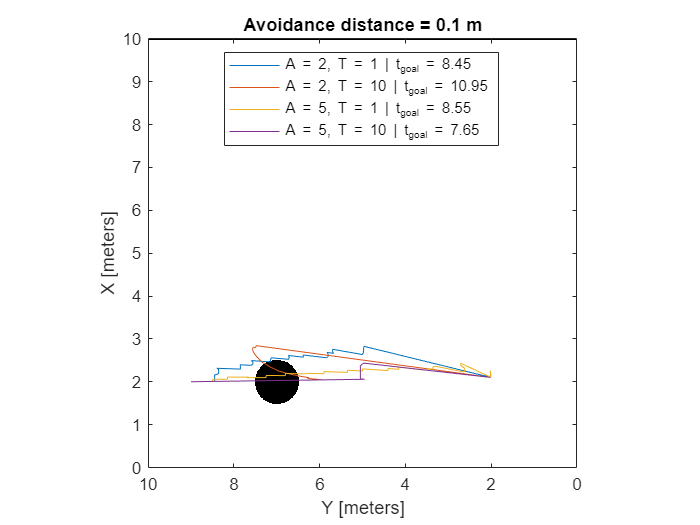


show(chair_map(chair_center(0.0, A, T_chair)));
hold on


%plot(pts(:,1), pts(:,2), '--s')

for trial = 1:4
plot(state_hist{trial}(:,1), state_hist{trial}(:,2))
    if trial == 1
        A = 2; T_chair = 1;
    elseif trial == 2
        A = 2; T_chair = 10;
    elseif trial == 3
        A = 5; T_chair = 1;
    elseif trial == 4
        A = 5; T_chair = 10 ;
    end
end
hold off
legend(legend_str, 'Location','north')
title("Avoidance distance = " + poten.avoidance_distance + " m")

%plot_scans(ranges, angles, [robot_state 0])

view(-90,90);

function xy = chair_center(t, A, T)
    x = 2;
    y = 7 - A*sin(2*pi*t / T);
    xy = [x;y];
end

function binary_map = chair_map(chair_xy)
resolution = 100;
binary_map = binaryOccupancyMap(10,10,resolution);
[X,Y] = meshgrid(0:1/resolution:10,0:1/resolution:10);

% Make walls
ind = (X == min(X(:))) | (X == max(X(:))) | (Y == min(Y(:))) | (Y == max(Y(:)));
x = X(ind);
y = Y(ind);
xy = [x y];
xy_ones = ones(size(x));
setOccupancy(binary_map, xy, xy_ones);

% Make chair
[xy, xy_ones] = occupancy_circle(X, Y, ...
            0.5, chair_xy(1), chair_xy(2));
if any(xy)
    setOccupancy(binary_map, xy, xy_ones);
end
inflate(binary_map, 1/resolution)

end

function [xy, xy_ones] = occupancy_circle(X, Y, r, x_c, y_c)
ind = (X-x_c).^2 + (Y-y_c).^2 <= r^2;
x = X(ind);
y = Y(ind);
xy = [x y];
xy_ones = ones(size(x));
end